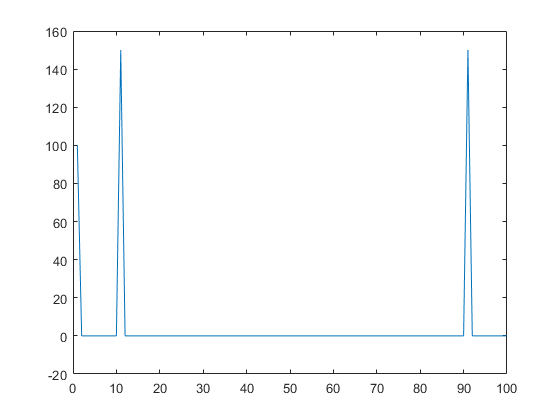

%zad1
tx=0.1;
fp=1000;
fcos=100;
fsin=100;
t=(0:1/fp:0.1-1/fp);
h=3*cos(2*pi*fcos*t)+sin(2*pi*fsin*t);
h=h+ones(1,100);
H=fft(h);
plot(real(H));

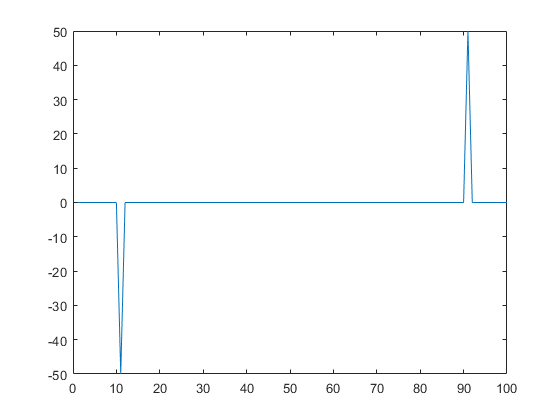

plot(imag(H));

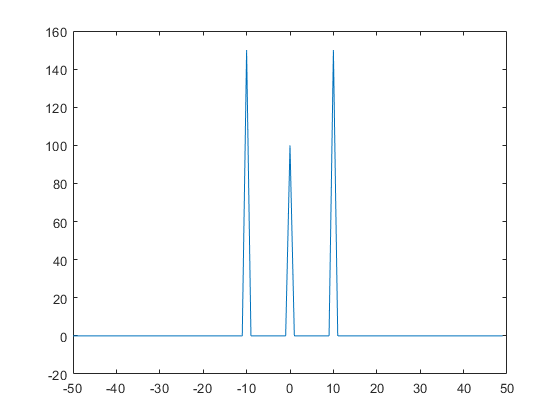


plot(-50:49, real([H(51:100) H(1:50)]));

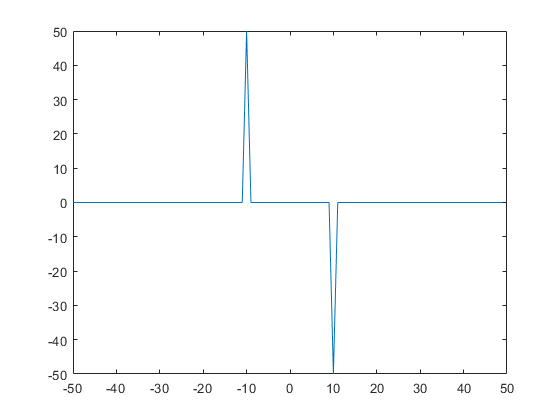

plot(-50:49, imag([H(51:100) H(1:50)]));

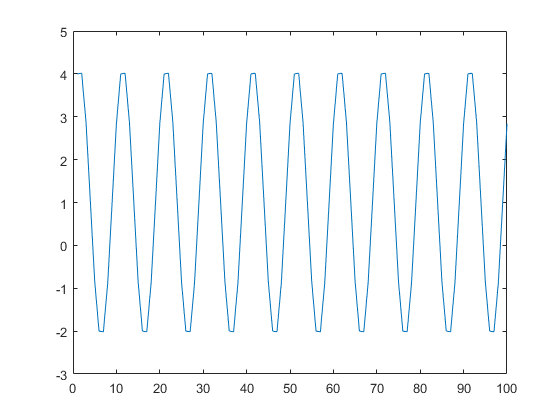


y=ifft(H);
plot(real(y));

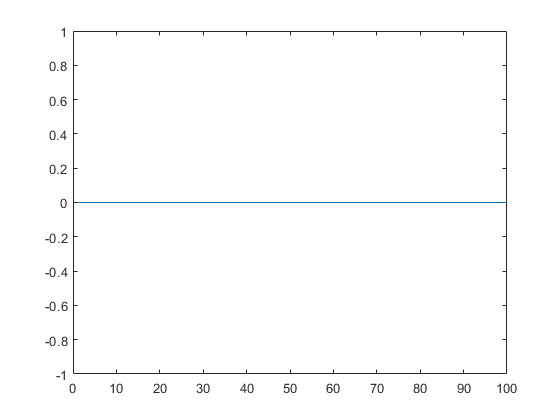

plot(imag(y));

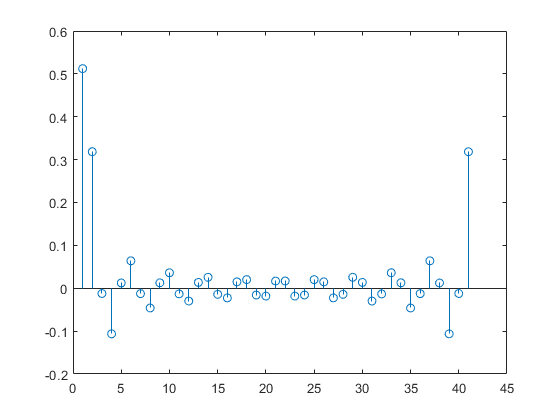

%zad2
fp=8000;
Hre=[1 ones(1,10) zeros(1,20) ones(1,10)];
Him=zeros(1,41);
H=Hre+j*Him;
hz=ifft(H);
stem(real(hz));

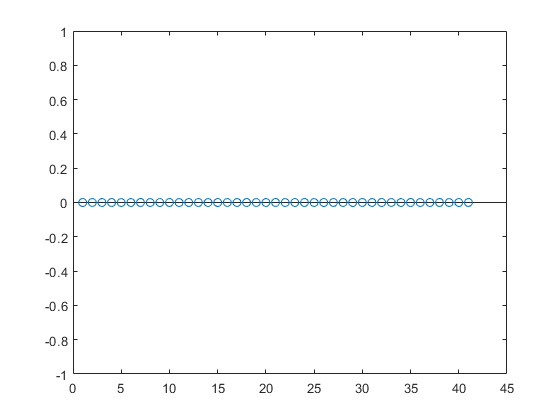

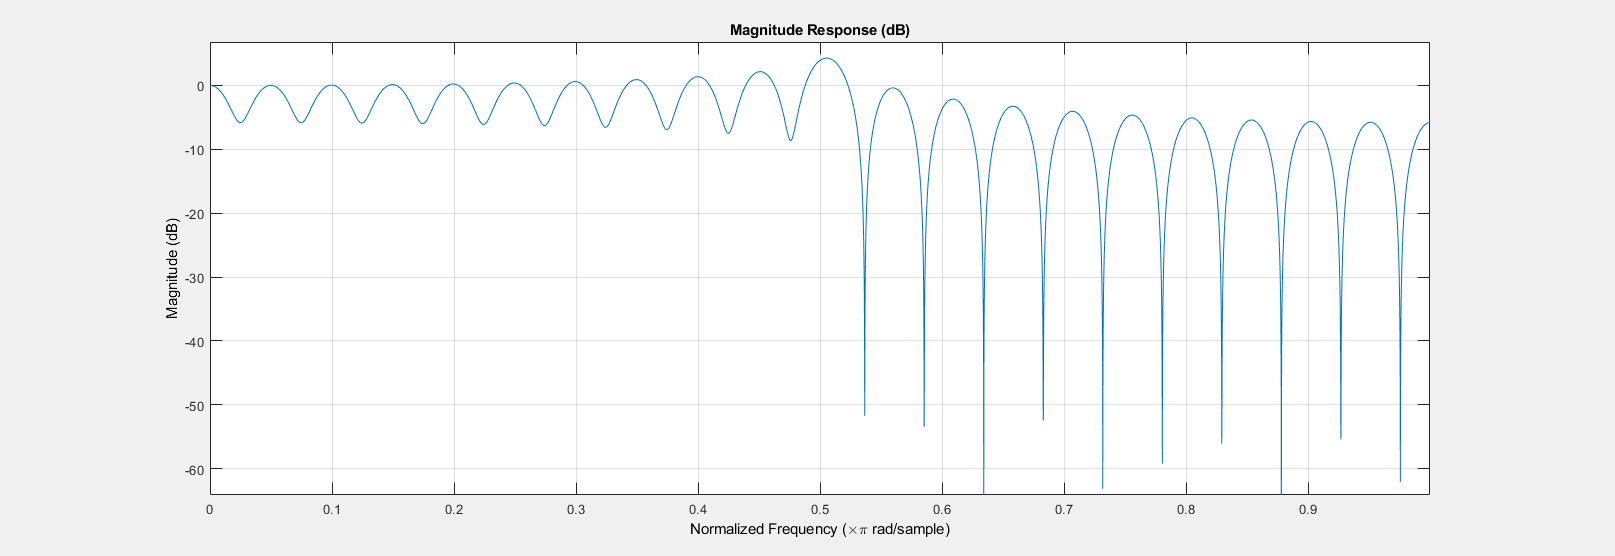

stem(imag(hz));
hre=real(hz);
fvtool(hre,1);

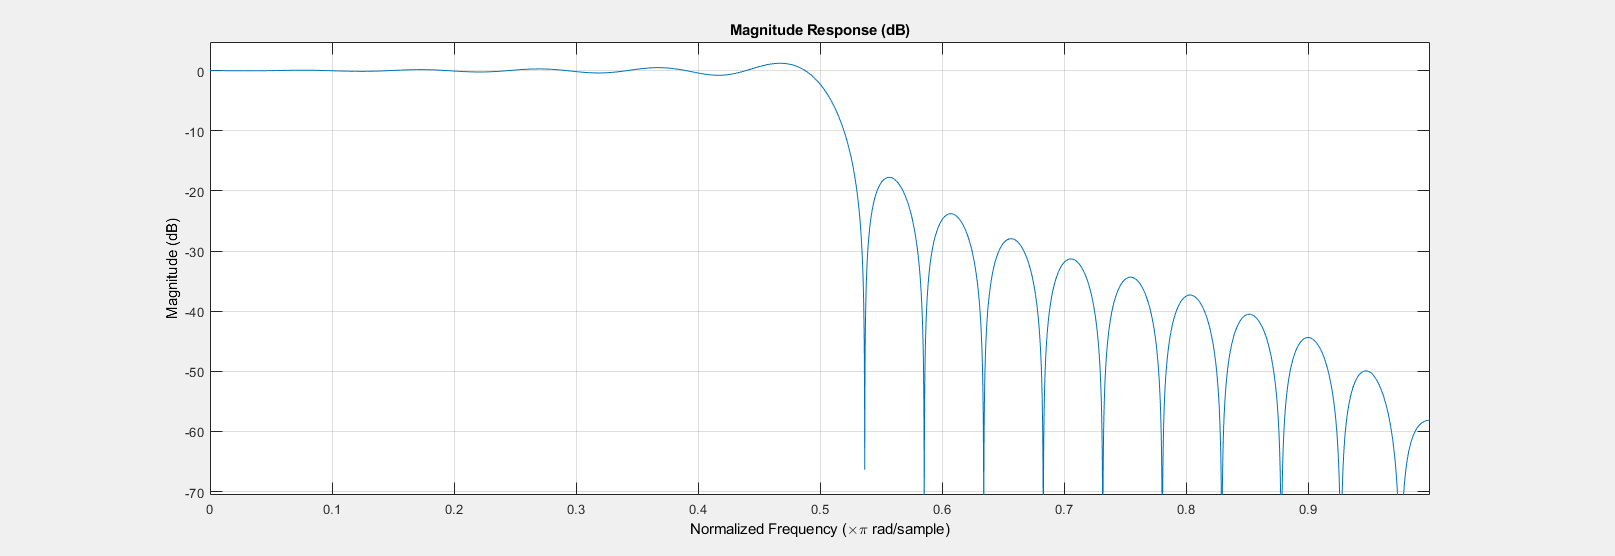

h=[hre(21:41) hre(1:20)];
fvtool(h,1);

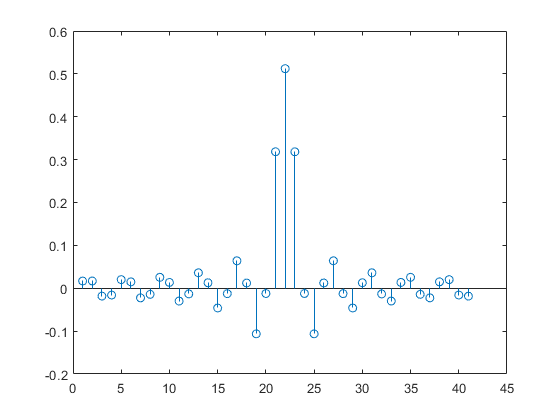

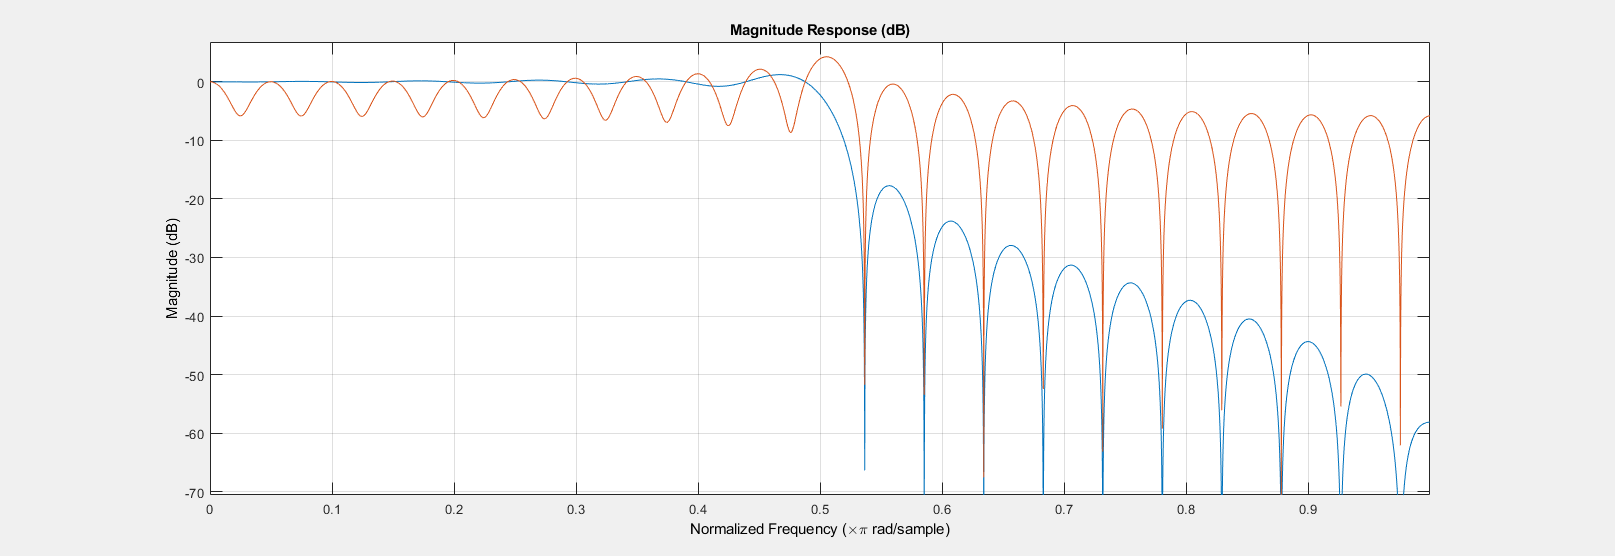

stem(h);
fvtool(h,1,hre,1);

Initializing Window Designer..

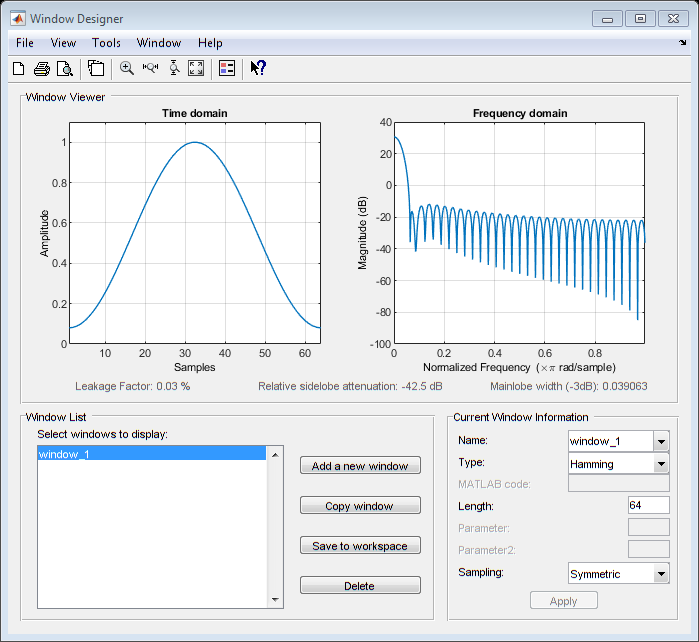

... done. 


windowDesigner;

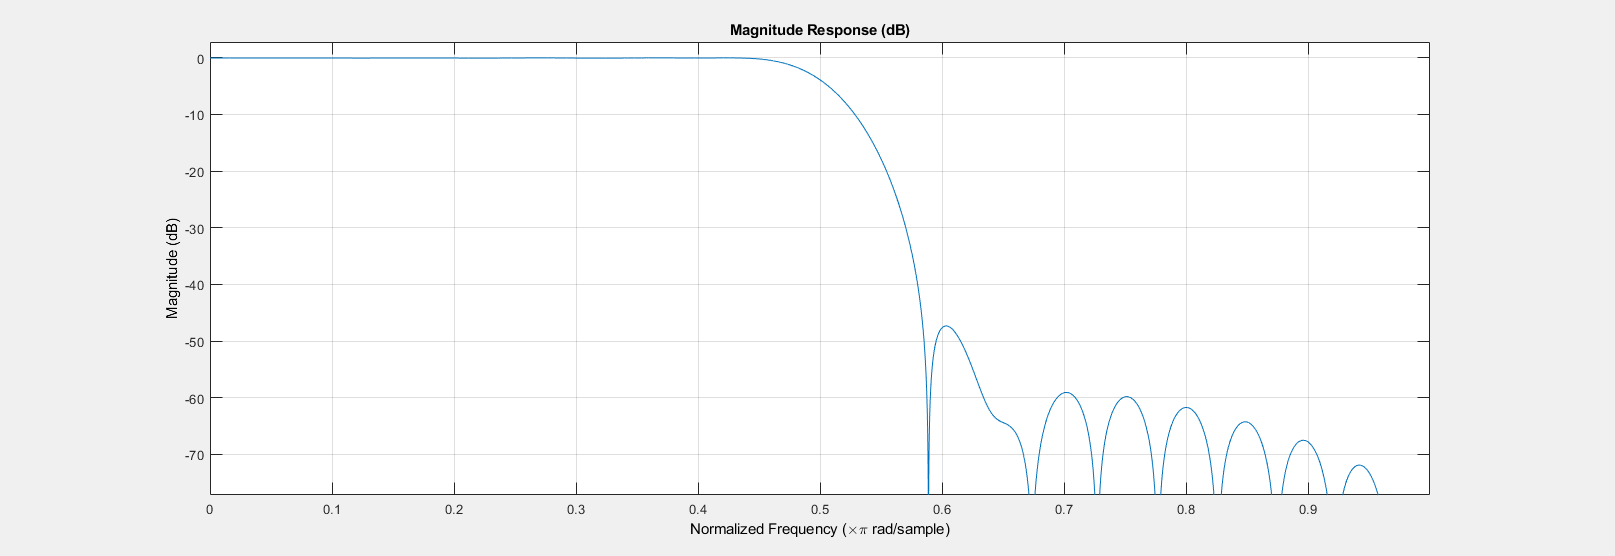

fvtool(h.*okno1',1);

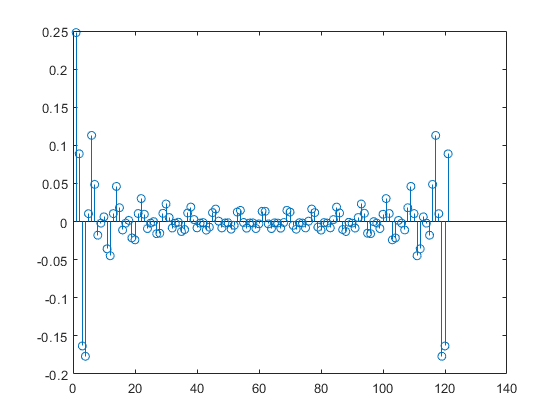

%zad3
fp=8000;
Hre=[0 zeros(1,15) ones(1,15) zeros(1,60) ones(1,15) zeros(1,15)];
Him=zeros(1,121);
H=Hre+j*Him;
hz=ifft(H);
stem(real(hz));

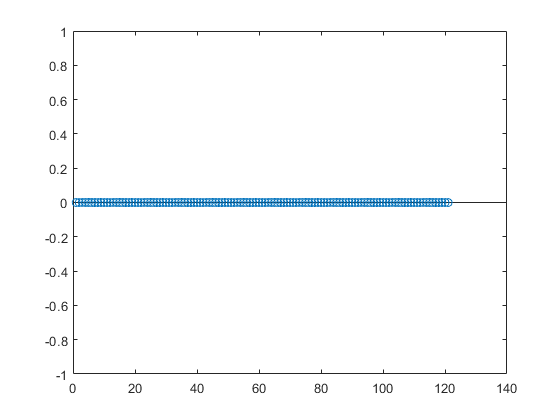

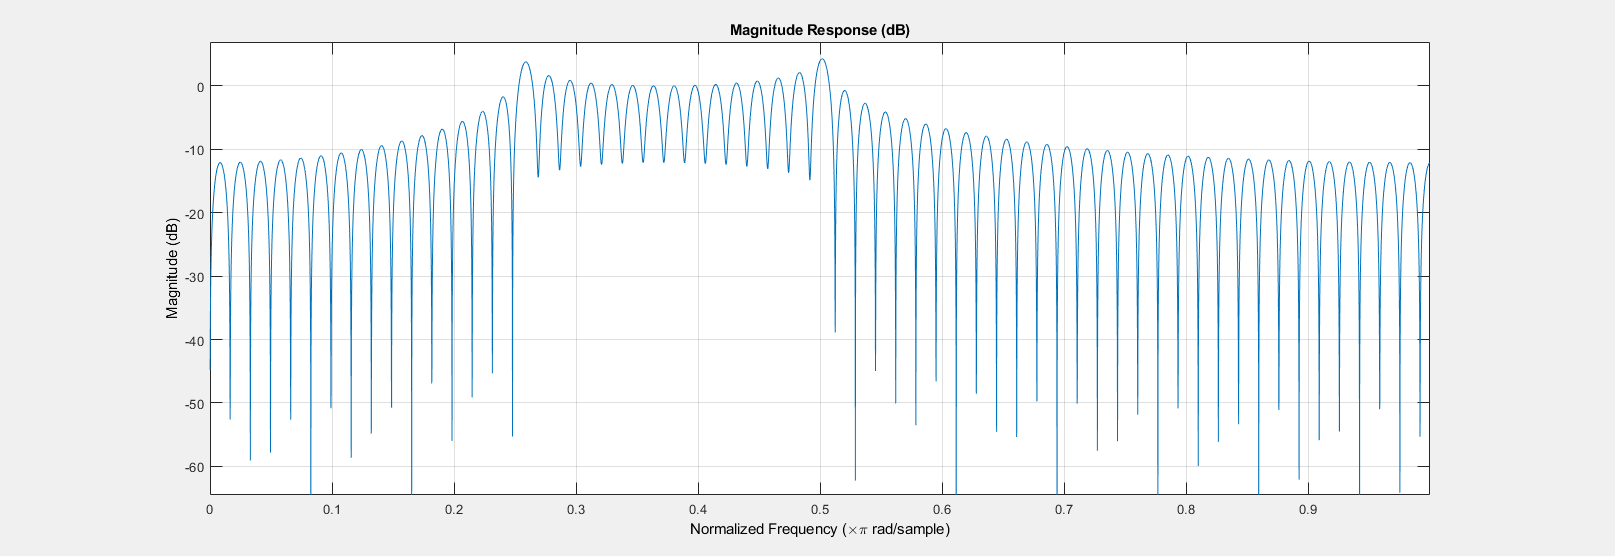

stem(imag(hz));
hre=real(hz);
fvtool(hre,1);

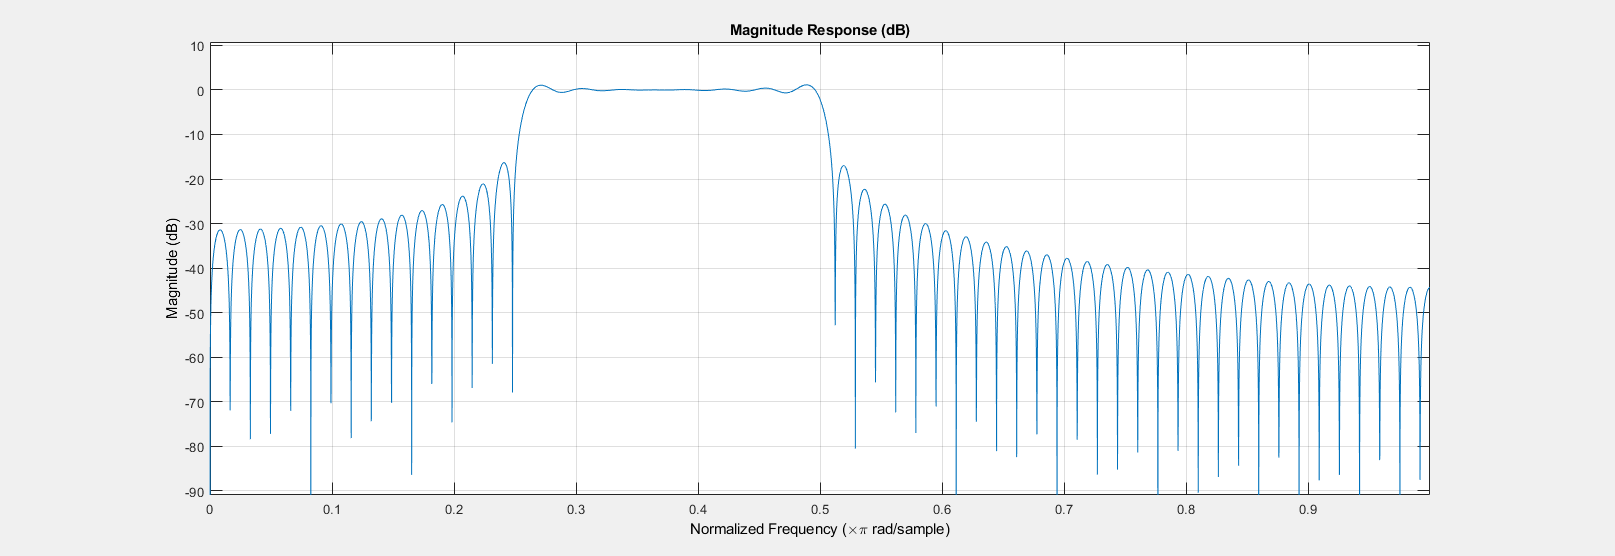

h=[hre(61:121) hre(1:60)];
fvtool(h,1);

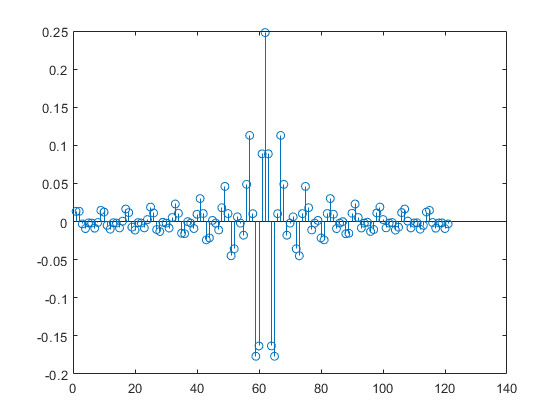

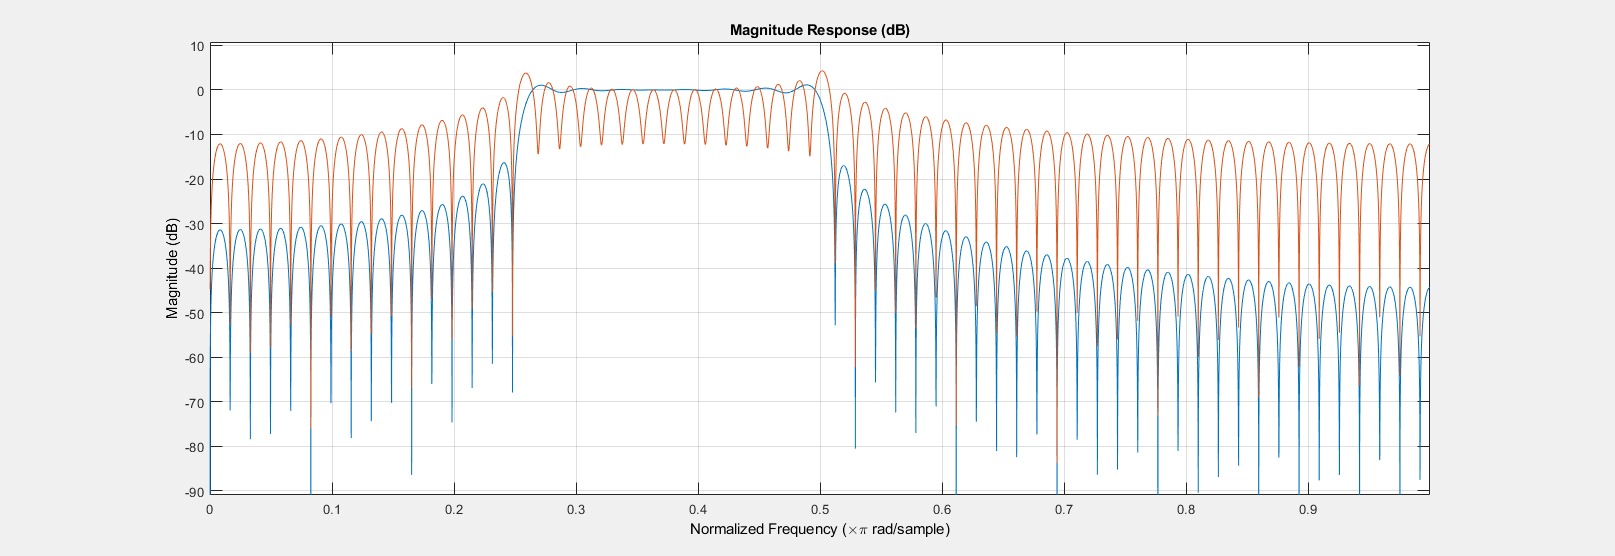

stem(h);
fvtool(h,1,hre,1);

Initializing Window Designer..

... done. 


windowDesigner;

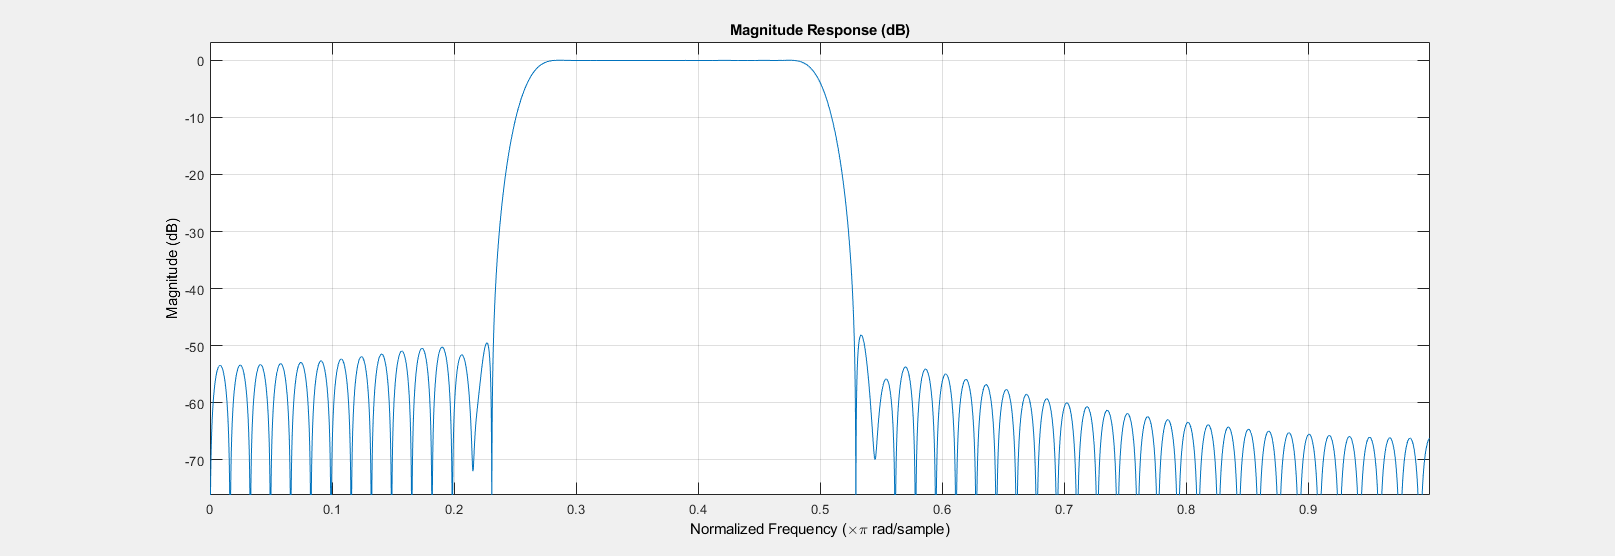

fvtool(h.*okno2',1);